# Part 3- Generation and Processing of Speech Signals

Defining basic variables 

clear all
N = 2^16;
n = 0:N-1;
d1 = 0.212410146;
d2 = 0.322977372;
d = mod(d1+d2,0.5);

Reading the signal and cutting it to be with length of 2^16

[x,f] = audioread("data_example_data_Witney_Carson.wav");
x = x(1:N);

Playing the signal

sound(x,f);

Finding the power of the signal

P = bandpower(x)

P = 0.0021

Generating the noised signal

a = 50*sqrt(P) .* ones(1,3);
W = [1.6+0.1*d1,1.6+0.1*d,3]';
z = (a*cos(W*n))';
y = x + z;
y'

ans =     6.8290   -2.4297   -2.3374   -1.4961    6.4073   -2.6558   -2.8875    0.0664    5.2544   -2.3220   -3.7970    1.9589    3.6681   -1.7276   -4.6840    3.8226    2.0849   -1.2316   -5.1713    5.2339    0.8525   -1.1796   -4.9877    5.9020    0.2158   -1.7208   -4.0181    5.7612    0.2116   -2.8003   -2.4061    4.9233    0.6180   -4.1931   -0.4638    3.7380    1.1564   -5.4554    1.4409    2.6163    1.4435   -6.2396    2.8817    1.8841    1.1841   -6.2716    3.6094    1.7328    0.2666   -5.4861


Playing the noised signal

sound(y,f);

Plotting the noised signal as a function of the time

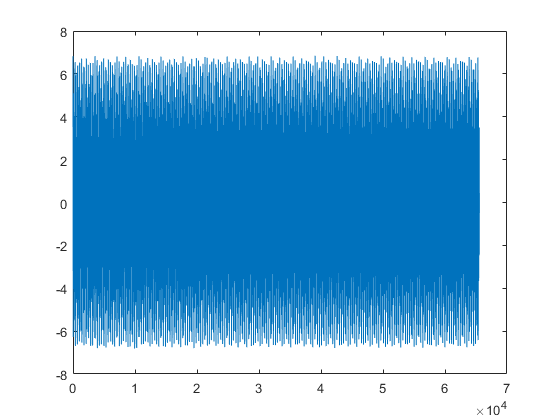

figure
plot(n,y);

Looking at the signal in the domain

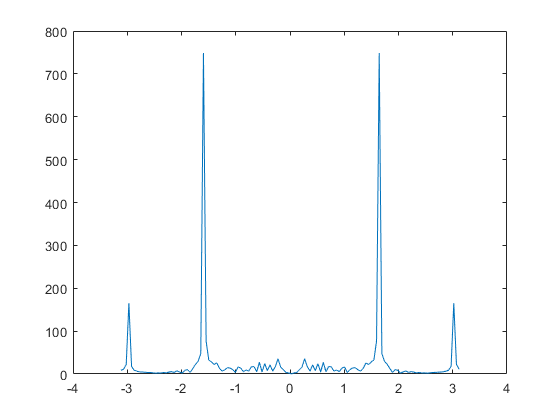

Y = fft(y);
plot_in_domain(Y)

Decimating y and z in time

y2 = y(1:2:end);
z2 = z(1:2:end);

Plotting the transform of z2

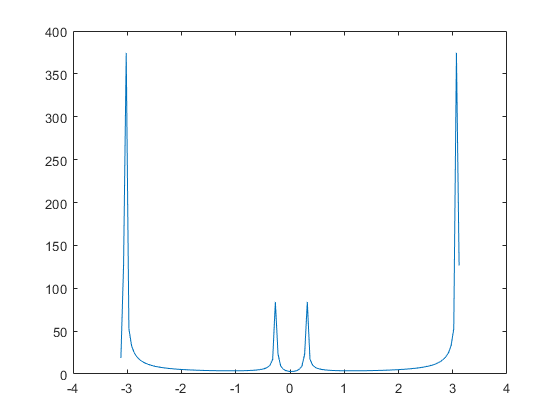

Z2 = fft(z2);
plot_in_domain(Z2);

Plotting y2

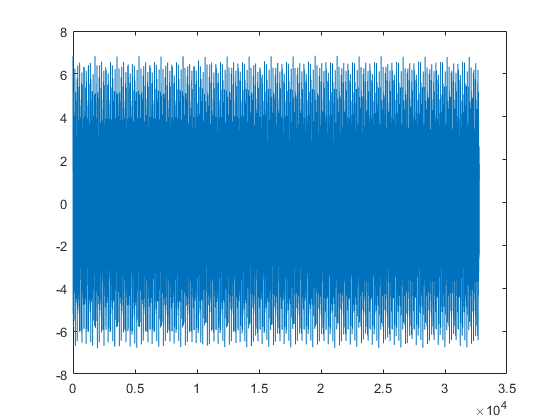

figure
plot(y2);

Plotting Y2  in the domain 

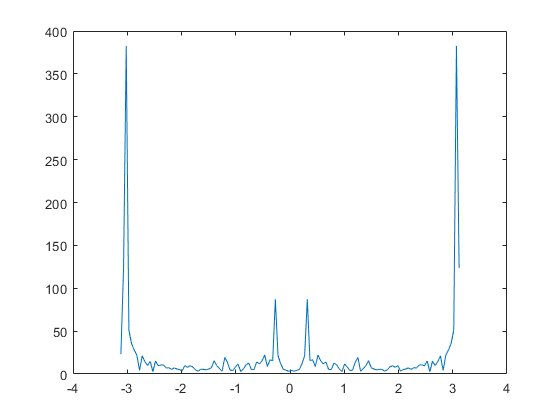

Y2 = fft(y2);
plot_in_domain(Y2);

Playing y2

sound(y2,f/2);

function plot_in_domain(X)
    M = 128;
    X_plot = X(1:size(X,1)/M:end);
    X_plot = circshift(X_plot,M/2);
    w = 2*pi/M * [-(M-1)/2:(M-1)/2];
    figure
    plot(w,abs(X_plot));
end